# MSessionExplorer.Merge

Ignore code in this section

if exist('isRun', 'var') && isRun
    se1 = seRaw.Duplicate;
    se1.RemoveTable('spikeTime', 'LFP');
    se2 = se1.Duplicate;
    se2.RemoveEpochs(254:265);
    se3 = se1.Duplicate;
    se3.RemoveEpochs(260:265);
else
    edit MSessionExplorer.Examples.Merge
    return;
end

**Description**

help MSessionExplorer.Merge

  Combine multiple MSessionExplorer objects into one by vertically concatenating data
  
    se = Merge(se1, se2, se3, ...)
  
  Inputs
    se1, se2, se3, ...      Arbitrary number of MSessionExplorer objects. 
  Output
    se                      The merged MSessionExplorer object



**Example 1**

**Concatenate three sessions**

First, let's look at the contents of the objects that we are going to merge. Although having different numbers of epoch, they must all have the same set of tables with matching columns. 

se1.Preview

tot
                    tableType        tableData      referenceTime 
                  _____________    _____________    ______________

    behavTime     'eventTimes'     [265×6 table]    [265×1 double]
    behavValue    'eventValues'    [265×5 table]    []            
    hsv           'timeSeries'     [265×4 table]    [265×1 double]
    adc           'timeSeries'     [265×5 table]    [265×1 double]

userData
    sessionInfo: [1×1 struct]
        satInfo: [1×1 struct]
        hsvInfo: [1×1 struct]
      intanInfo: [1×1 struct]
    preTaskData: [1×1 struct]
      spikeInfo: [1×1 struct]



se2.Preview

tot
                    tableType        tableData      referenceTime 
                  _____________    _____________    ______________

    behavTime     'eventTimes'     [253×6 table]    [253×1 double]
    behavValue    'eventValues'    [253×5 table]    []            
    hsv           'timeSeries'     [253×4 table]    [253×1 double]
    adc           'timeSeries'     [253×5 table]    [253×1 double]

userData
    sessionInfo: [1×1 struct]
        satInfo: [1×1 struct]
        hsvInfo: [1×1 struct]
      intanInfo: [1×1 struct]
    preTaskData: [1×1 struct]
      spikeInfo: [1×1 struct]



se3.Preview

tot
                    tableType        tableData      referenceTime 
                  _____________    _____________    ______________

    behavTime     'eventTimes'     [259×6 table]    [259×1 double]
    behavValue    'eventValues'    [259×5 table]    []            
    hsv           'timeSeries'     [259×4 table]    [259×1 double]
    adc           'timeSeries'     [259×5 table]    [259×1 double]

userData
    sessionInfo: [1×1 struct]
        satInfo: [1×1 struct]
        hsvInfo: [1×1 struct]
      intanInfo: [1×1 struct]
    preTaskData: [1×1 struct]
      spikeInfo: [1×1 struct]



Then, let's do the merging. The following 3 expressions are all equivalent. Note the warning messages, which are expected by combining 3 independent sessions. Before fixing this issue, however, you cannot safely use any data slicing functionalities that depend on reference times. (A future version may try to resolve the monotonicity automatically.)

seMerged = Merge(se1, se2, se3);

seMerged = se1.Merge(se2, se3);

seArray = [se1 se2 se3]'

seArray =   3×1 MSessionExplorer array with properties:

    supportedTableTypes
    tot
    userData
    tableNames
    isEventTimesTable
    isEventValuesTable
    isTimesSeriesTable
    numEpochs
    epochInd
    isVerbose


seMerged = seArray(1).Merge(seArray(2:end));

Here shows contents of the new object. It has 777 epochs which is the sum of that in the 3 input objects. userData structs are concatenated into a struct array due to their consistent fields, otherwise they will be store in a cell array. 

seMerged.Preview

tot
                    tableType        tableData      referenceTime 
                  _____________    _____________    ______________

    behavTime     'eventTimes'     [777×6 table]    [777×1 double]
    behavValue    'eventValues'    [777×5 table]    []            
    hsv           'timeSeries'     [777×4 table]    [777×1 double]
    adc           'timeSeries'     [777×5 table]    [777×1 double]

userData
  3×1 struct array with fields:

    sessionInfo
    satInfo
    hsvInfo
    intanInfo
    preTaskData
    spikeInfo



Unlike reference times, the epochInd from the end of one session to another automatically increment after merging. 

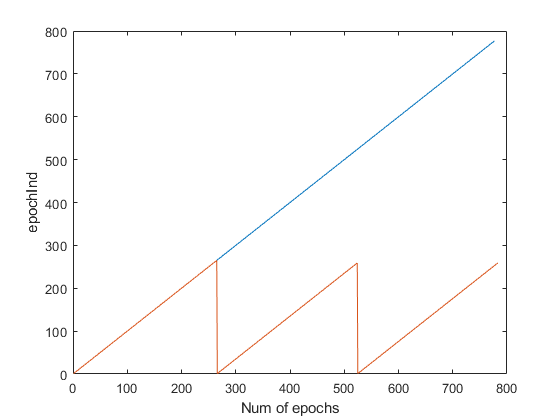

plot(seMerged.epochInd); hold on
plot([se1.epochInd; se3.epochInd; se3.epochInd]);
xlabel('Num of epochs')
ylabel('epochInd')